%% 3. A script file for check the corectness of the implementation and the evaluation of the results
% Load the point of the stereo image (Mire)
P1_1 = load ('Mire/Mire1.points')

P1_1 =    240   137
   445   120
   465   119
   703   137
   442   408
   250   473
   459   410
   685   472
   241   513
   454   439


P2_2 = load ('Mire/Mire2.points')

P2_2 =     52   136
   288   119
   306   118
   519   136
   294   407
    72   472
   310   407
   508   469
    61   510
   303   437



% Load the poit of the stereo image (Rubik)
% P1_1 = load ('Rubik/Rubik1.points')
% P2_2 = load ('Rubik/Rubik2.points')

row_number = size(P1_1, 1);
ones_column = ones(row_number, 1);

% convert in homogeneous cordinate
P1 = [P1_1, ones_column]

P1 =    240   137     1
   445   120     1
   465   119     1
   703   137     1
   442   408     1
   250   473     1
   459   410     1
   685   472     1
   241   513     1
   454   439     1


P1 = P1';
% want to consider a row vector

P2 = [P2_2, ones_column]

P2 =     52   136     1
   288   119     1
   306   118     1
   519   136     1
   294   407     1
    72   472     1
   310   407     1
   508   469     1
    61   510     1
   303   437     1


P2 = P2';


% Call the function for calculate the normalized fondamental matrix 
F = EightPointsAlgorithm(P1', P2, row_number);

U =     0.0034    0.8937    0.4487
   -0.0023   -0.4487    0.8937
    1.0000   -0.0041    0.0005


D =     1.0000         0         0
         0    0.0000         0
         0         0    0.0000


V =     0.0050   -0.9125   -0.4091
   -0.0019    0.4091   -0.9125
   -1.0000   -0.0053   -0.0003


F_N = EightPointsAlgorithmN(P1, P2, row_number); % Pass P1 transpose for the produìct inside the function 

U =    -0.0604   -0.0061    0.9982
    0.9980   -0.0207    0.0603
    0.0203    0.9998    0.0074


D =     0.7088         0         0
         0    0.7054         0
         0         0    0.0041


V =    -0.0033    0.0611   -0.9981
   -0.0177   -0.9980   -0.0610
    0.9998   -0.0174   -0.0044



% evaluate the results of f:
% chceck the epipolar constraints x'Fx = 0,  check for every point
for i = 1:1:row_number
    % evaluate the epipolar constraint for not normalized point 
    result(i) = P2(:,i)' * F * P1(:,i);
   
    % evaluate the epipolar constraint for not normalized point
    result_N(i) = P2(:,i)' * F_N * P1(:,i);

end

rangoF = rank(F_N);

img1 = imread('Mire/Mire1.pgm');

img2 = imread('Mire/Mire2.pgm');

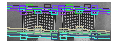


% this function allows me to visualize the epipolar line give the two
% images with the two pair of point
visualizeEpipolarLines( img1, img2, F_N, P1_1, P2_2);


% looking for the epipole
%needs to applicate the decomposition svd to F matrix F = UWV' and select
%the last columns of U and V

[U W V] = svd (F_N);
last_col_U = U(1:2,end)

last_col_U =     0.9975
    0.0711


last_col_V = V(1:2,end)

last_col_V =    -0.9977
   -0.0672
